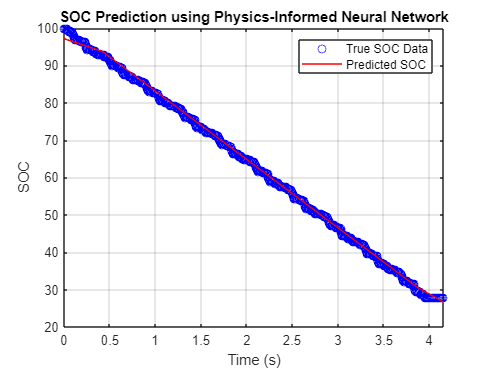

clc;
clear;
close all;

% Load internal parameters of the 2RC network
load('ro.mat'); % Ohm
load('r1.mat'); % Ohm
load('r2.mat'); % Ohm
load('c1.mat'); % F
load('c2.mat'); % F

% Load the true SOC data
load('socnew.mat'); % Example SOC data
load('timenew.mat'); % Time data


r0 = R0(1:10:end);
r1 = R1(1:10:end);
r2 = R2(1:10:end);
c1 = C1(1:10:end);
c2 = C2(1:10:end);

% Ensure the data is correctly formatted
SOC_data = Measured_SOC(1:10:end); % Ensure column vector
t_data = RecordingTime_Hours(1:10:end); % Ensure column vector

% Define the neural network architecture for Physics-Informed Network
layers = [
    featureInputLayer(1, 'Normalization', 'none', 'Name', 'input')
    fullyConnectedLayer(107, 'Name', 'fc1')
    reluLayer('Name', 'relu1')
    %fullyConnectedLayer(15, 'Name', 'fc2')
    %reluLayer('Name', 'relu2')
    %fullyConnectedLayer(10, 'Name', 'fc3')
    %reluLayer('Name', 'relu3')
    fullyConnectedLayer(1, 'Name', 'output')
    regressionLayer('Name', 'regressionoutput')
];

% Training options
options = trainingOptions('adam', ...
    'MaxEpochs', 5, ...
    'InitialLearnRate', 0.001, ...
    'MiniBatchSize', 1, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', false);

% Prepare training data
inputs = t_data;
targets = SOC_data;

% Train the network
net = trainNetwork(inputs, targets, layers, options);

% Predict SOC using the trained network
t_test = linspace(min(t_data), max(t_data), 100)';
predictedSOC = predict(net, t_test);

% Plot the results
figure;
plot(t_data, SOC_data, 'bo', 'DisplayName', 'True SOC Data');
xlim([min(t_data), max(t_data)]);
hold on;
plot(t_test, predictedSOC, 'r-', 'DisplayName', 'Predicted SOC');
xlabel('Time (s)');
ylabel('SOC');
legend;
title('SOC Prediction using Physics-Informed Neural Network');
grid on;


% Calculate the physics-informed loss on training data
predicted_train_SOC = predict(net, inputs);
loss = physicsInformedLoss(predicted_train_SOC, targets, inputs, r0, r1, r2, c1, c2);
fprintf('Final Physics-Informed Loss: %.6f\n', loss);

Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physics-Informed Loss: 0.551457
Final Physic


% Define the physics-informed loss function

function loss = physicsInformedLoss(predictions, targets, inputs, r0, r1, r2, c1, c2)
    residuals = predictions - targets;
  voltage_response = @(t, SOC) SOC .* r0 + (r1 / c1) .* exp(-t / (r1 .* c1)) + (r2 / c2) .* exp(-t / (r2 .* c2));
    voltage_pred = voltage_response(inputs, predictions);
    
    voltage_true = voltage_response(inputs, targets);
    physics_loss = mean((voltage_pred - voltage_true).^2);
    
    data_loss = mean(residuals.^2);
    loss = data_loss + physics_loss;
end